## **Nombres: **

- **Jorge Fernando Bustos Mendez (221160068)**

- **Nicolas Narvaez Arturo (221160075)**

# **Concolución Discreta **

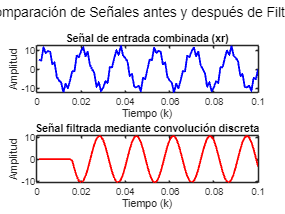

Ts = 0.001;
Fs = 1/Ts;
for k = 1:100
    x(k) = 10*sin(2*pi*60*Ts*k);
    r(k) = 2.5*sin(2*pi*400*Ts*k);
    t(k) = Ts*k;
    xr(k) = x(k) + r(k);
end
filtro = designfilt('lowpassfir', 'FilterOrder', 15, 'PassbandFrequency', 100, 'StopbandFrequency', 150, 'DesignMethod', 'ls', 'SampleRate', 1000);
coeficientes_filtro = filtro.Coefficients;

y_convolucion = zeros(size(xr));

for n = 16:length(xr)
    y_convolucion(n) = sum(xr(n:-1:n-15) .* coeficientes_filtro);
end

figure;

subplot(2,1,1);
plot(t, xr, 'b', 'LineWidth', 1.5);
title('Señal de entrada combinada (xr)');
xlabel('Tiempo (k)');
ylabel('Amplitud');
hold on;

subplot(2,1,2);
plot(t, y_convolucion, 'r', 'LineWidth', 1.5);
title('Señal filtrada mediante convolución discreta');
xlabel('Tiempo (k)');
ylabel('Amplitud');

sgtitle('Comparación de Señales antes y después de Filtrar');

### Respuesta al impulso del filtro

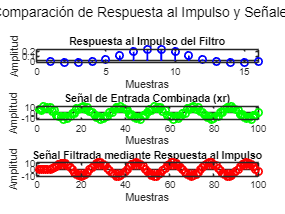

respuesta_impulso = impz(filtro);
y_convolucion = conv(xr, coeficientes_filtro, 'full');

figure;

subplot(3,1,1);
stem(respuesta_impulso, 'b', 'LineWidth', 1.5);
title('Respuesta al Impulso del Filtro');
xlabel('Muestras');
ylabel('Amplitud');

subplot(3,1,2);
stem(xr, 'g', 'LineWidth', 1.5);
title('Señal de Entrada Combinada (xr)');
xlabel('Muestras');
ylabel('Amplitud');
hold on;

subplot(3,1,3);
stem(y_convolucion(1:length(xr)), 'r', 'LineWidth', 1.5);
title('Señal Filtrada mediante Respuesta al Impulso');
xlabel('Muestras');
ylabel('Amplitud');

sgtitle('Comparación de Respuesta al Impulso y Señales');